## **Worked Example 9.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input dynamics matrix and calculate its eigenvalues
A = [0 1 0 0; 0 0 -5 0; 0 0 0 1; -5 0 0 0];
eig(A)

ans =   -2.2361 + 0.0000i
  -0.0000 + 2.2361i
  -0.0000 - 2.2361i
   2.2361 + 0.0000i


% Input the remaining matrices and create a state-space system
B = [0; 0; 0; 1 / 8];
C = [1 0 0 0];
D = [0];
sys = ss(A, B, C, D);

% Compute the observability matrix of the system and compute its determinant 
Wo = obsv(sys)

Wo =      1     0     0     0
     0     1     0     0
     0     0    -5     0
     0     0     0    -5


det(Wo)

ans = 25

% Create a vector of the desired eigenvalue locations 
P = [-12; (-8 + 10i); (-8 - 10i); -10];

% Calculate the state feedback gain vector K
L = place(A', C', P)

L = 1.0e+03 *

    0.0380    0.6360   -1.1056   -3.9410


L = L'

L = 1.0e+03 *

    0.0380
    0.6360
   -1.1056
   -3.9410


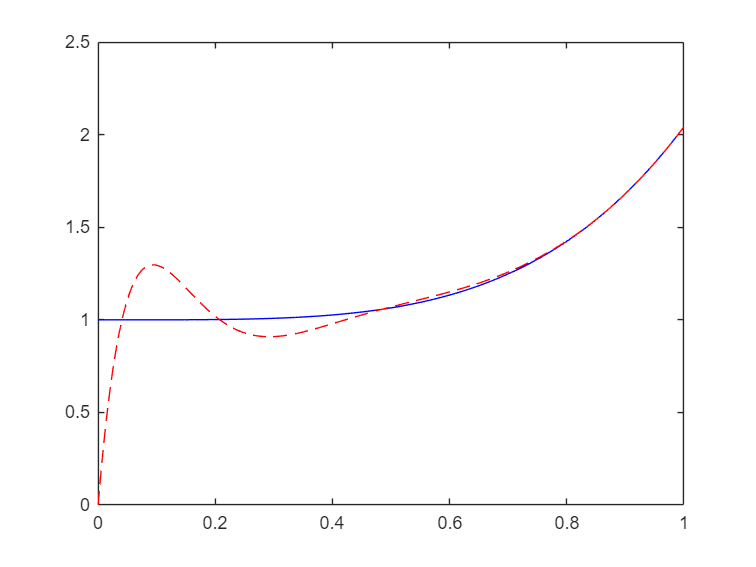

% Create a state-space system which includes the observer
A_o = [A zeros(size(A)); (L * C) (A - L * C)];
B_o = [B; B];
C_o = [C zeros(size(C)); zeros(size(C)) C];
D_o = [0];
sys_o = ss(A_o, B_o, C_o, D_o);

% Create the time input and input force vctors
T = 0 : 0.001 : 1;
U = sin(3 * T);

% Set the initial conditions
z0 = [1; 0; 0; 0; 0; 0; 0; 0];

% Simulate and store the response Y and the states Z at each time-step T
[Y, T, Z] = lsim(sys_o, U, T, z0);

% Plot the evolution of the states along with their observer estimates
plot(T, Z(:, 1), '-b', T, Z(:, 5), '--r')

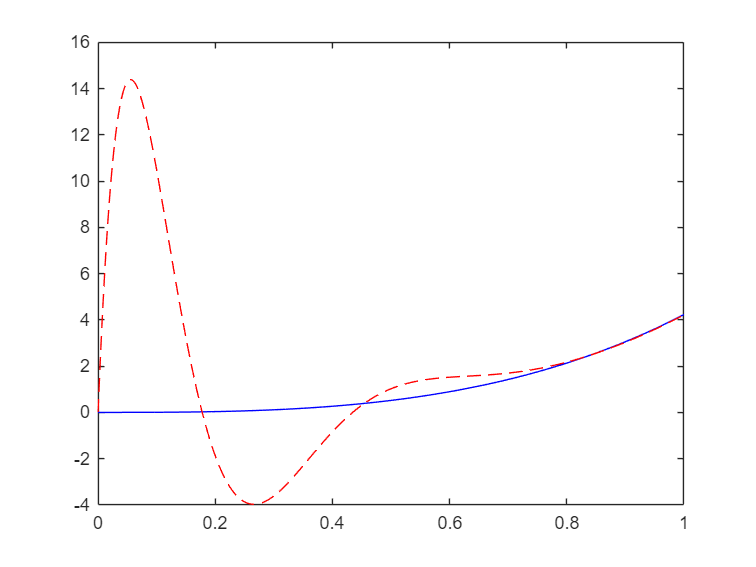

plot(T, Z(:, 2), '-b', T, Z(:, 6), '--r')

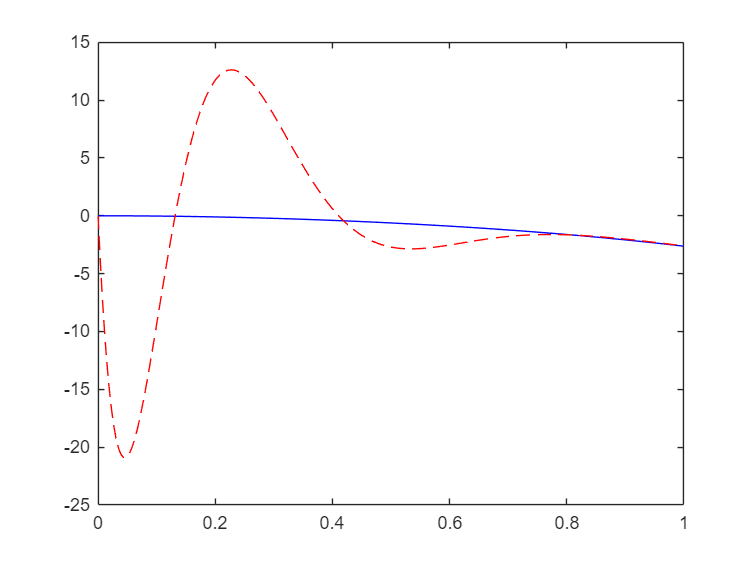

plot(T, Z(:, 3), '-b', T, Z(:, 7), '--r')

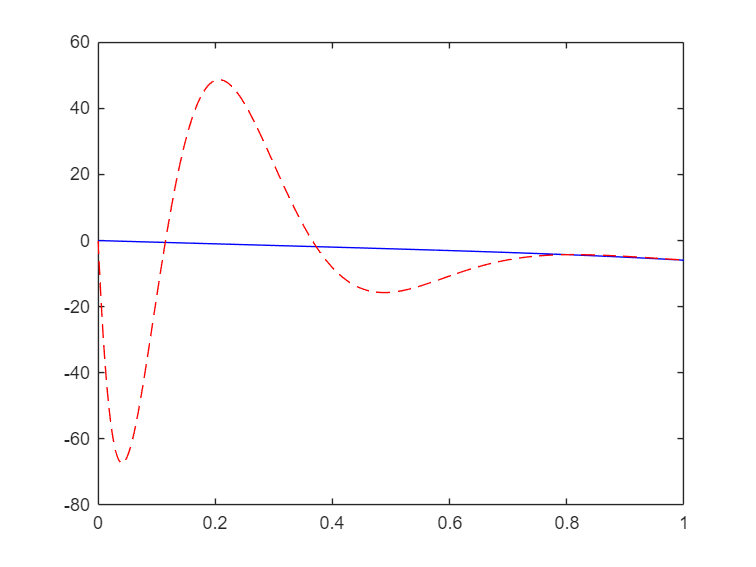

plot(T, Z(:, 4), '-b', T, Z(:, 8), '--r')